# MNI mean map

root_dir = 'D:\File\work_file\Dataset\Brain\openFCD\';

sub_dirs = dir(root_dir); sub_dirs(1:2) = [];
sub_dirs = sub_dirs([sub_dirs.isdir]);
sub_num = length(sub_dirs);

atlas_surferdir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\';
disp_paths(atlas_surferdir)

    1: E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\    



XYZ_flat2mni = MRI_read_Data([atlas_surferdir,'XYZ_flat2mni.nii.gz']);

sMRI [229,193,193,3] res:[1,1,1]


XYZ_mni2flat = MRI_read_Data([atlas_surferdir,'XYZ_mni2flat.nii.gz']);

sMRI [229,193,193,3] res:[1,1,1]


saveREF_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\fcd_atlas\';
mni_REF = MRI_read_Data([saveREF_dir,'WG_mean_mni_cat12.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


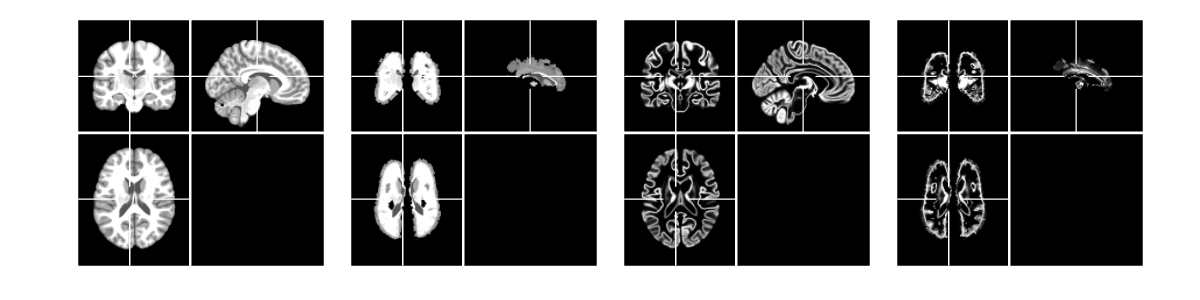


mniF_frac = MRI_warp(XYZ_mni2flat,mni_frac,'BST','interp_type',1);
mniF_REF = MRI_warp(XYZ_mni2flat,mni_REF,'BST','interp_type',1,'smoothness',0);

figure; lay_sub(1,4)
next; plot_mri({mni_frac,mniF_frac,mni_REF,mniF_REF},'off','enhance',@amp)
lay_fig([12,3])

feature_num = 9;
if_saveall = 0;
remake_iter = 0;

feature_names = {'T1','T1.GM','T1.grad','T1.WG','T1.thickness','T2','T1.depth','T1.WGmap','T1.curvtureABS'};

saveAtlas_dir = ['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\inflat_atlas\iter',num2str(remake_iter),'\'];
if_saveAtlas = 1;
mkdir_silent(saveAtlas_dir)

map_L1sum = repmat({mni_frac.data*0},1,feature_num);
map_L2sum = map_L1sum;

bad_subjs = [82,94,149,151,156,158,160];
i_list = setdiff(1:sub_num,bad_subjs);

if if_saveall
    alldata = repmat({repmat(0*mni_gray.data,1,1,1,length(i_list))},feature_num,1);
end

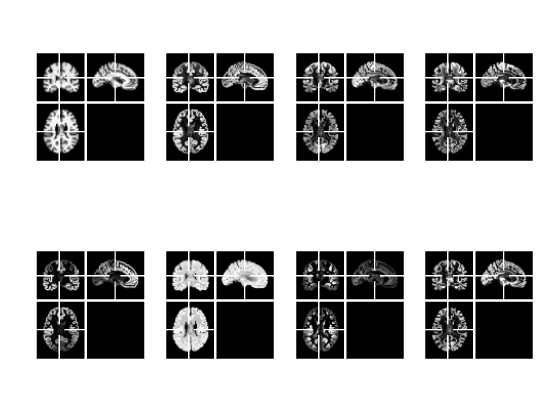

输入参数的数目不足。

出错 next>subnext (第 23 行)
if length(p) == 2

出错 next (第 13 行)
    ax = subnext(varargin{:});

出错 plot_mri (第 38 行)
                    next; axis off

initAtlas_dir = ['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\inflat_atlas\iter',num2str(remake_iter-1),'\'];
feature_names = {'T1','T1.GM','T1.grad','T1.WG','T1.thickness','T2','T1.depth','T1.WGmap','T1.curvtureABS'};

for i = 1:length(feature_names)
    temp = MRI_read_Data([initAtlas_dir,'mni_',feature_names{i},'.mean.nii.gz'],'verbose',0);
    mapV_mean{i} = temp.data;
    temp = MRI_read_Data([initAtlas_dir,'mniF_',feature_names{i},'.mean.nii.gz'],'verbose',0);
    mapF_mean{i} = temp.data;
    map_mean_max(i) = max(temp.data,[],"all");
end

figure; lay_sub(2,4)
next; plot_mri(mapV_mean,'off','enhance',@amp)

lay_fig([12,5])

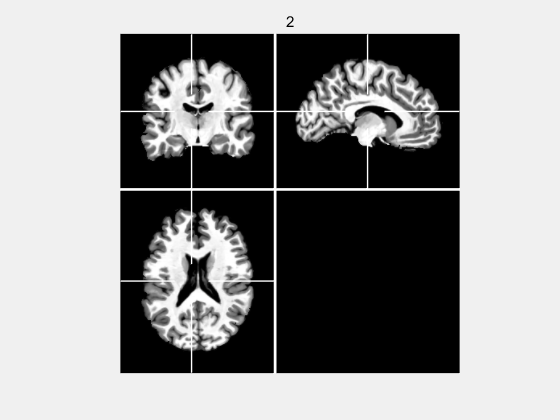

  E 00:00:00   1% [........................................] R 00:00:00 Progress: 2/163 

  E 00:04:31 100% [=======================================>] R 00:00:16 Progress: 163/163 


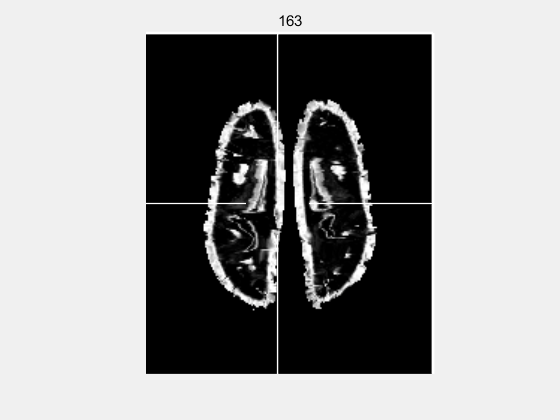

reg_iter = 40;
reg_box = [30,30,30; 200,170,150]';
save_feature_idx = [2];

% frac_tailstr = '.pvc.frac_reg';
frac_tailstr = '.reg.norm';

if_plotall = 1;

t_tic= tic;
i_use = 0*i_list;
ii = 0;
figure('Visible','on'); next
for i_sub = 1:length(i_list)
    disp_wait(i_sub,length(i_list))
    sub_dir = sub_dirs(i_list(i_sub)).name;
    inflat_dir = [root_dir,sub_dir,'/save/inflat/'];
    inflat_file = [inflat_dir,'T1.pvc.frac_inflat.nii.gz'];
    roi_file = [root_dir,sub_dir,'\T1_rb\FLAIR_roi_reg.nii.gz'];
    frac_file = [root_dir,sub_dir,'\T1_rb\T1',frac_tailstr,'.nii.gz'];

    if isfile(inflat_file) && isfile(frac_file) && ~isfile(roi_file)
        T1_frac = MRI_read_Data(frac_file,'verbose',0);
        hemi_reg = MRI_read_Data([root_dir,sub_dir,'\T1_rb\T1.hemi_reg.nii.gz'],'verbose',0);
        XYZ_inflat = MRI_read_Data([inflat_dir,'XYZ_subj2mniF.nii.gz'],'verbose',0);
        XYZ_inflat.data(XYZ_inflat.data == 0) = NaN;

        XYZ_deflat = MRI_read_Data([inflat_dir,'XYZ_subj2mniF.nii.gz'],'verbose',0);

        LAB = T1_frac.data.*(hemi_reg.data>0);
        LAB = mat_cut(3*LAB-1,0);

        clf; next; plot_mri(LAB,'off','enhance',@amp); title(i_sub)
        pause(0.25)

        ii = ii+1;
        for j = 1:feature_num
            if ~ismember(j,save_feature_idx)
                continue
            end

            [data,warp_type] = get_multiFeatures(LAB,[root_dir,sub_dir],j);

            clf; next; plot_mri(data,'off','enhance',@amp); title(i_sub)
            pause(0.5)

            data = single(data).*(hemi_reg.data>0);
            warp_type = 1;
            if warp_type == 1
                data_inflat = MRI_warp(XYZ_inflat,data);
            else
                data_inflat = [];
                data_inflat.data = single(data);
            end
            FEA = remove_nan(data_inflat.data);

            % if if_plotall % for paper figure
            %     mask = imgaussfilt3(single(imgaussfilt3(single(LAB>0),2)>0),1);
            %     data_masked = amp(data,1e-3)+0.1*mask;
            %     mask = imgaussfilt3(single(imgaussfilt3(single(~isnan(XYZ_inflat.data(:,:,:,1))),2)>0),1);
            %     FEA_masked = amp(FEA,1e-3)+0.1*mask;
            %     figure; next; next; plot_mri({LAB,data_masked,FEA_masked},'z','enhance',@amp,'cross_width',0);
            %     figure; next; plot_mri(XYZ_inflat,'z','if_detrend',1,'cross_width',0)
            %     pause(0.25)
            % end

            cla; plot_mri(FEA,'z','enhance',@amp); title(i_sub)
            pause(0.25)

            if remake_iter>0
                FEA0 = FEA;
                if j == 1
                    [D,FEA] = imreg_demons(remove_nan(FEA),mapF_mean{j},reg_iter,reg_box);
                else
                    FEA(box(1):box(4),box(2):box(5),box(3):box(6)) = imwarp(FEA(box(1):box(4),box(2):box(5),box(3):box(6)),D);
                end
            end

            % figure; next; plot_mri({FEA0,FEA,map_mean{j}},'off','enhance',@amp)

            if if_saveall
                alldata{j}(:,:,:,i_sub) = FEA;
            end

            if ii == 1
                if length(map_L1sum)<j
                    map_L1sum{j} = FEA;
                    map_L2sum{j} = FEA.^2;
                else
                    map_L1sum{j} = map_L1sum{j}*0;
                    map_L2sum{j} = map_L2sum{j}*0;
                end
            else
                map_L1sum{j} = map_L1sum{j} + FEA;
                map_L2sum{j} = map_L2sum{j} + FEA.^2;
            end
        end

        i_use(i_sub) = 1;
    end
    if mod(i_sub,10) == 1
        % 'ok';
        % plot_mri(MRI_warp(XYZ_flat2mni,map_L1sum{4},'BST'));
        % fig = gcf; fig.Name = "i_sub: "+i_sub;
    end
end


disp_toc(t_tic)

  |->  using 274.9s [=============================================] 2024-09-15 22:07:52


% i_listuse = i_list(i_use>0);
% if if_saveall
%     for j = 1:feature_num
%         feature_data = alldata{j}(:,:,:,i_use>0);
%         save([root_dir,'/feature_data',num2str(j,'%02d'),'.mat'],'feature_data','i_listuse')
%     end
% end

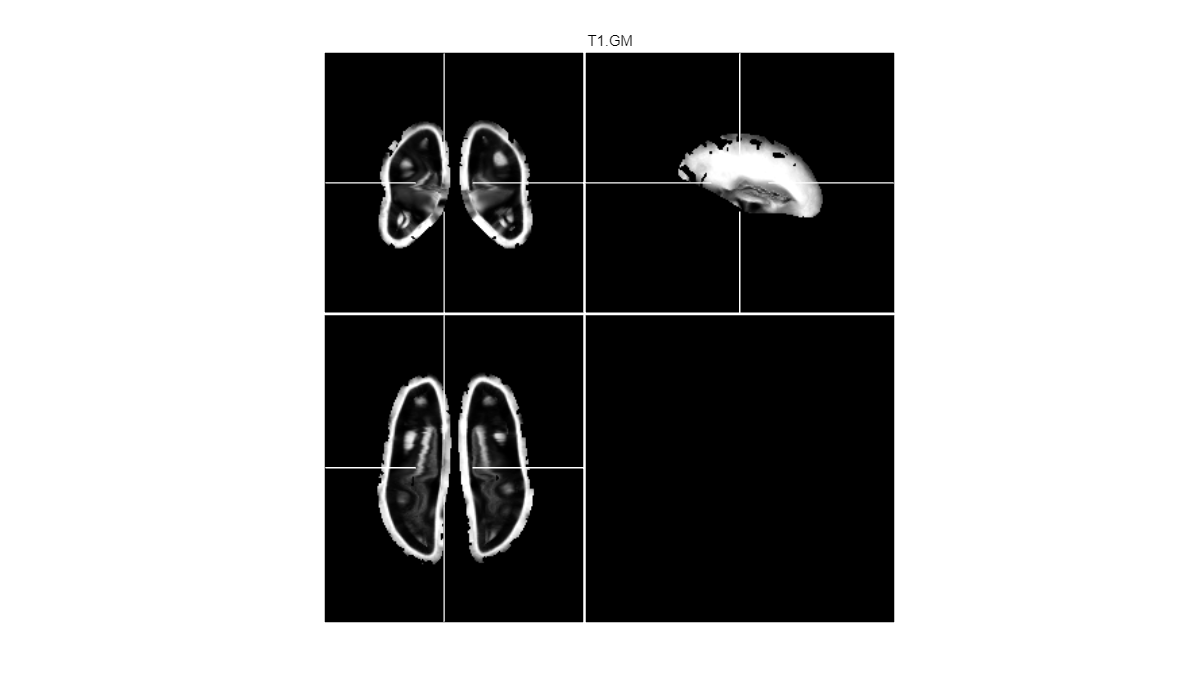

mask_mniV = imgaussfilt3(single(mni_mask.data),0.5);
mask_mniF = MRI_warp(XYZ_mni2flat,mask_mniV,'BST'); mask_mniF = mask_mniF.data;

i_num = sum(i_use);
% mask_fullsm = imgaussfilt3(single(remove_nan(mask_full.data)),1);
for j = 1:feature_num
    mapF_mean{j} = remove_nan(map_L1sum{j}/i_num);
    map_std{j} = (remove_nan(map_L2sum{j})/i_num - mapF_mean{j}.^2).^0.5;
end

switch warp_type
    case 1
        save_tag = 'mniF_';
    case 2
        save_tag = 'mniV_';
end

figure; %lay_sub(2,3)
for j = 1:feature_num
    if ndims(mapF_mean{j}) < 4
        if if_saveAtlas && ismember(j,save_feature_idx)
            data = mapF_mean{j};
            next; plot_mri(data,'off','enhance',@amp); title(feature_names{j})
            MRI_save_File(data,[saveAtlas_dir,save_tag,feature_names{j},'.mean.nii.gz'])
        end
    end
end
lay_fig([12,7])

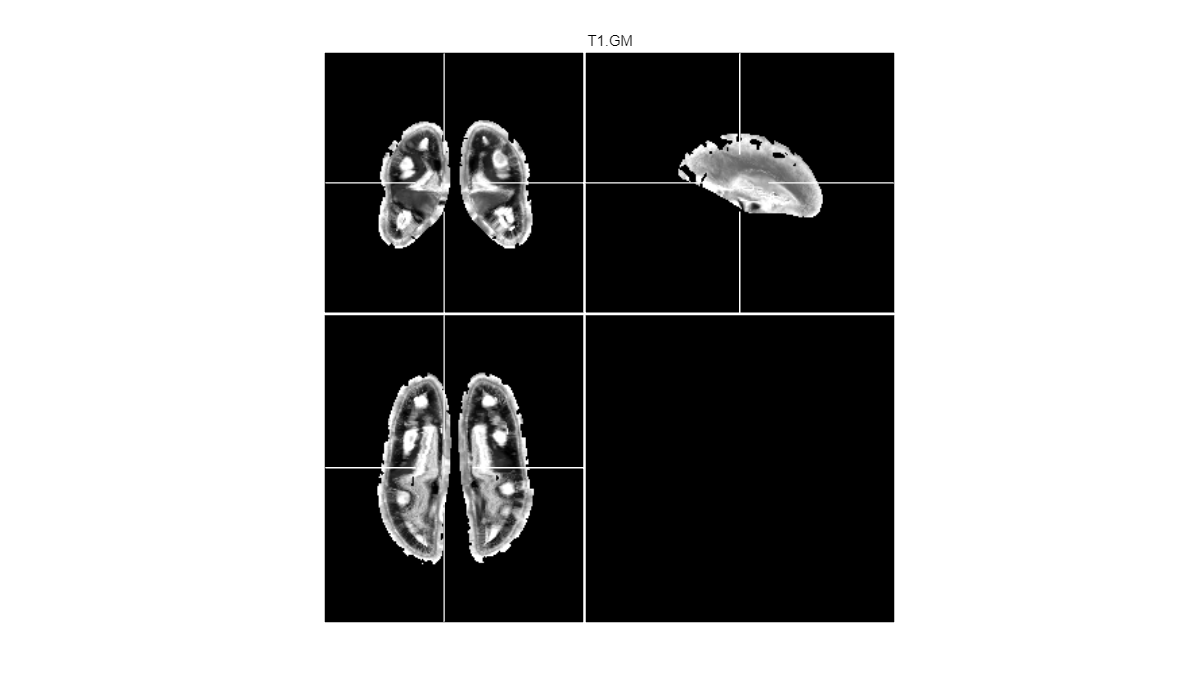


figure; % lay_sub(2,3)
for j = 1:feature_num
    try
        if if_saveAtlas && ismember(j,save_feature_idx)
            data = map_std{j};
            next; plot_mri(data,'off','enhance',@amp); title(feature_names{j})
            MRI_save_File(data,[saveAtlas_dir,save_tag,feature_names{j},'.std.nii.gz'])
        end
    catch
        axis off
    end
end
lay_fig([12,7])

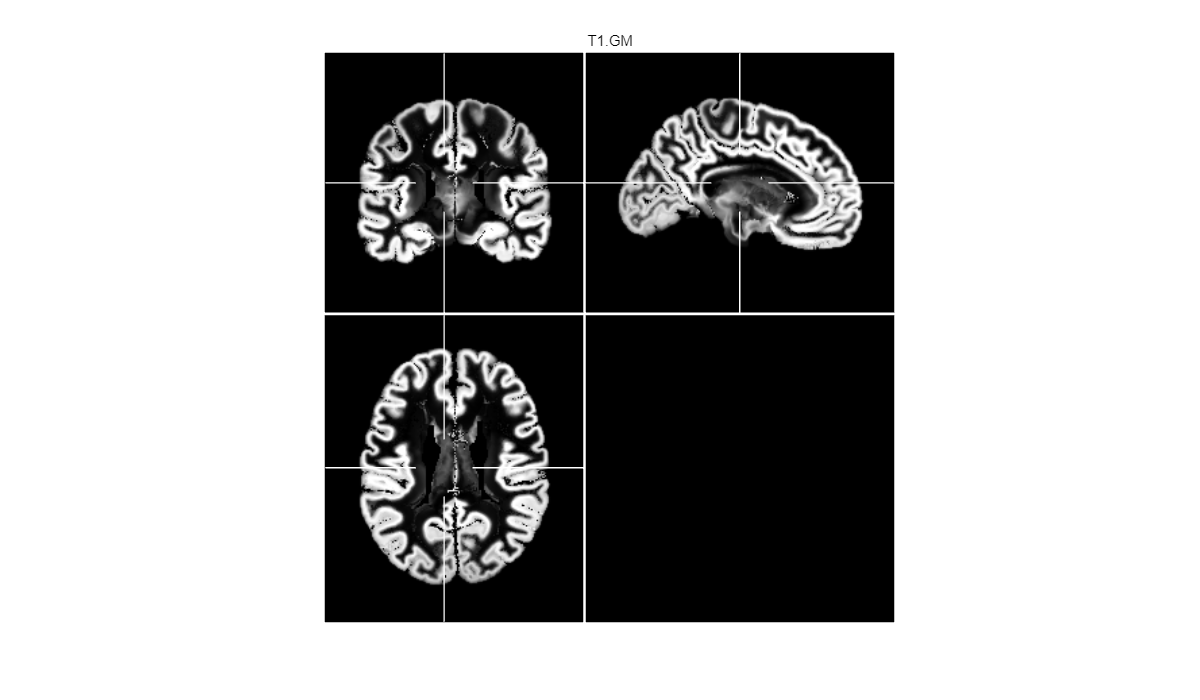

figure; % lay_sub(2,3)
for j = 1:feature_num
    if ndims(mapF_mean{j}) < 4
        if if_saveAtlas && ismember(j,save_feature_idx)
            mni_mapmean{j} = MRI_warp(XYZ_flat2mni,mapF_mean{j},'BST');
            mni_mapmean{j} = remove_nan(mni_mapmean{j});
            mni_mapmean{j} = mni_mapmean{j}.data.*mask_mniV;
            next; plot_mri(mni_mapmean{j},'off','enhance',@amp); title(feature_names{j})
            MRI_save_File(mni_mapmean{j},[saveAtlas_dir,'mni_',feature_names{j},'.mean.nii.gz'],'info',mni_gray)
        end
    end
end
lay_fig([12,7])

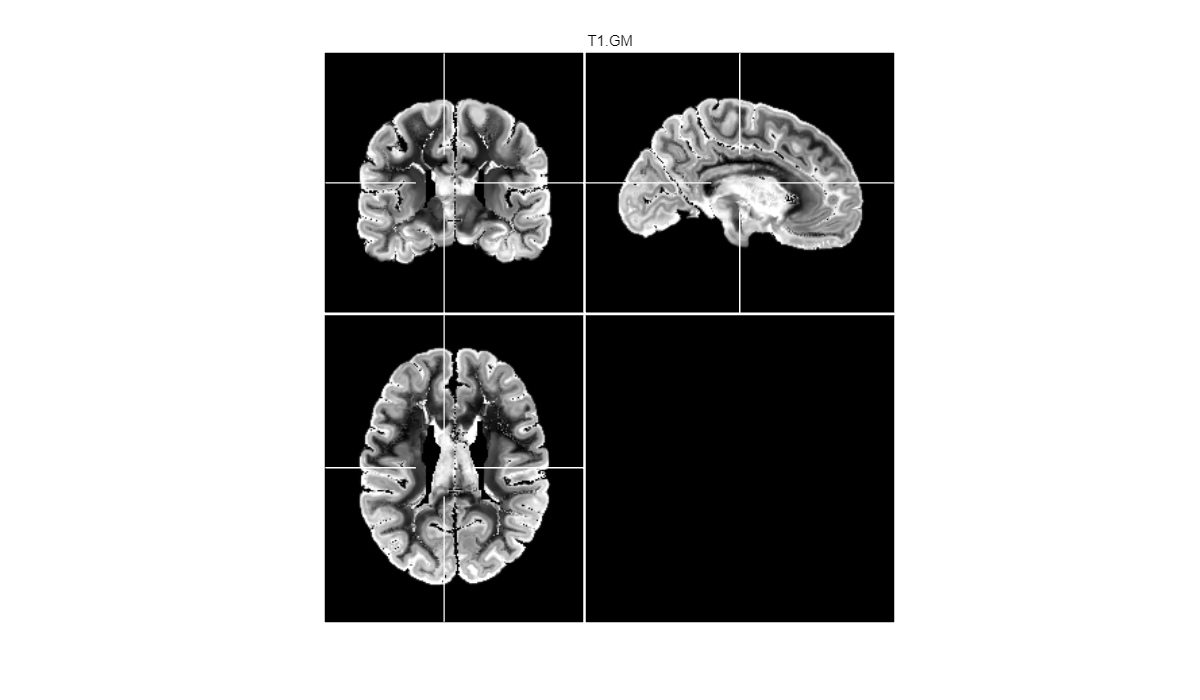

figure; % lay_sub(2,3)
for j = 1:feature_num
    if ndims(mapF_mean{j}) < 4
        if if_saveAtlas && ismember(j,save_feature_idx)
            mni_mapstd{j} = MRI_warp(XYZ_flat2mni,map_std{j},'BST');
            mni_mapstd{j} = remove_nan(mni_mapstd{j});
            mni_mapstd{j} = mni_mapstd{j}.data.*mask_mniV;
            next; plot_mri(mni_mapstd{j},'off','enhance',@amp); title(feature_names{j})
            MRI_save_File(mni_mapstd{j},[saveAtlas_dir,'mni_',feature_names{j},'.std.nii.gz'],'info',mni_gray)
        end
    end
end
lay_fig([12,7])

## mean and std in mniV space

% T1_mean = MRI_read_Data([saveAtlas_dir,'\mniV_T1.mean.nii.gz']);
% 
% GM = T1_mean;
% GM.data = mat_cut(1 - 1*abs(T1_mean.data - 1));
% 
% MRI_save_File(GM,[saveAtlas_dir,'\mniV_T1.GM.mean.nii.gz'])
% 
% figure;
% plot_mri(GM,'off','enhance',@amp);
% 
% temp = [saveAtlas_dir,'mniV_T1.WG.mean.nii.gz'];
% mri = MRI_read_Data(temp);
% mri_new = mni_gray;
% mri_new.data = mri.data;
% MRI_save_File(mri_new,temp)

fea_idx = 5;

ii = 0;
for i_sub = 1:length(i_list)
    disp_wait(i_sub,length(i_list))
    sub_dir = sub_dirs(i_list(i_sub)).name;

    frac_file = [root_dir,sub_dir,'\T1_rb\T1.reg.norm.nii.gz'];
    if isfile(frac_file) && ~isfile([root_dir,sub_dir,'\save\resMAP\FLAIR_roi_reg.nii.gz'])
        ii = ii+1;
        
        T1_frac = MRI_read_Data(frac_file,'verbose',0);
        LAB = mat_cut(3*T1_frac.data-1,0);

        [FEA,warp_type] = get_multiFeatures(LAB,[root_dir,sub_dir],fea_idx);

        if ii == 1
            map_L1sum = FEA;
            map_L2sum = FEA.^2;
        else
            map_L1sum = map_L1sum + FEA;
            map_L2sum = map_L2sum + FEA.^2;
        end
    end
end

  E 00:00:23 100% [=======================================>] R 00:00:01 Progress: 86/86 


mapV_mean = remove_nan(map_L1sum/ii);
mapV_std = (remove_nan(map_L2sum)/ii - mapV_mean.^2).^0.5;

MRI_save_File(mapV_mean,[saveAtlas_dir,'mniV_',feature_names{fea_idx},'.mean.nii.gz'],'info',mni_gray)
MRI_save_File(mapV_std,[saveAtlas_dir,'mniV_',feature_names{fea_idx},'.std.nii.gz'],'info',mni_gray)

## cortex mask in inflat space

mni_label = MRI_read_Data('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\brainsuit_raw\mri.svreg.label.nii.gz');

sMRI [229,193,193] res:[1,1,1]


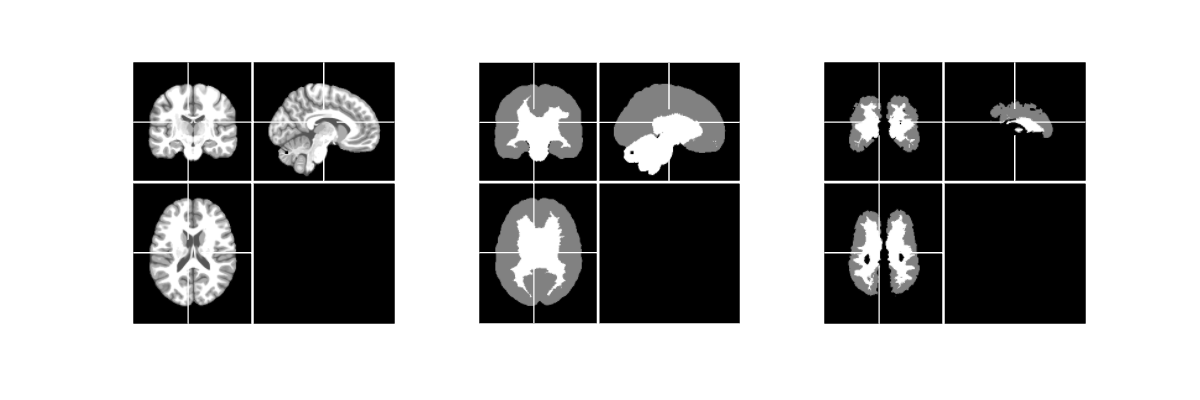

mni_label = mni_label.data;
cortex_maskV = 0*mni_label;
temp = (mni_label > 2000) | ((mni_label>1000) & (mni_label<2000));
cortex_maskV(temp) = 1;
temp = (mni_label == 2000) | ((mni_label>0) & (mni_label<1000));
cortex_maskV(temp) = 2;
cortex_maskF = MRI_warp(XYZ_mni2flat,cortex_maskV,'BST','interp_type',0);

surfer_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\';
MRI_save_File(uint8(cortex_maskV),[surfer_dir,'mni_cortex_mask.nii.gz'],'info',mni_gray)
MRI_save_File(uint8(cortex_maskF.data),[surfer_dir,'mniF_cortex_mask.nii.gz'],'info',mni_gray)

figure;
next; plot_mri({mni_frac,cortex_maskV,cortex_maskF},'off','enhance',@amp);
lay_fig([12,4])

data = MRI_read_Data('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\inflat_atlas\iter0\mniF_T1.WG.mean.nii.gz');

sMRI [229,193,193] res:[1,1,1]


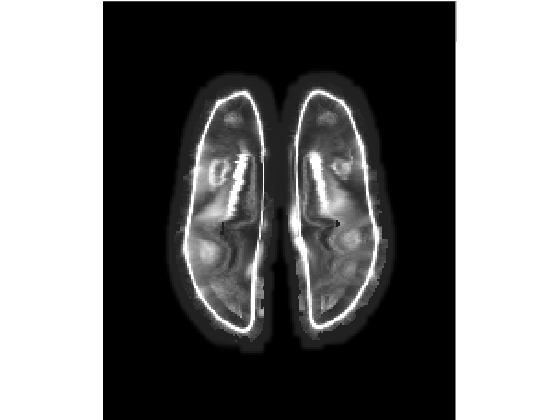

data = data.data;
mask = imgaussfilt3(single(imgaussfilt3(single(cortex_maskF.data>0),2)>0),1);
data_masked = amp(data,1e-3)+0.1*mask;
figure; next; plot_mri({data_masked},'z','enhance',@amp,'cross_width',0);

# load mean map from multiple source

% fea_names = {'T1','T1.grad','T1.WG','T1.thickness','T2','T1.depth'};
fea_names = {'T1','T1.GM','T1.thickness','T1.WG'};
% fea_names = {'frac','GM','thick','WG'};
load_tag = 'mean';

fea_num = length(fea_names);

% MAXs for std
map_MAXs = [0.6,0.4,30,0.4];

% MAXs for mean
map_MAXs = [2,1,20,1];

tic
mris = []; map_tex3D = [];  map_Ren3D = [];
for j = 1:fea_num
    % mri = mni_mapmean{j};

    temp = ['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\inflat_atlas\iter0\mni_',fea_names{j},'.',load_tag,'.nii.gz']; % mni or mniV
    % temp = ['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\fcd_atlas\',fea_names{j},'_',load_tag,'_cat12.nii.gz'];
    % temp = ['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\fcd_atlas\',fea_names{j},'.',load_tag,'.nii.gz'];

    mri = MRI_read_Data(temp,'verbose',0);
    mris{j} = mri.data;

    map_maxs(j) = prctile(mri.data(:),99);

    [map_tex3D{j},map_Ren3D{j}] = Pilo_gen(mri,'XYZ',mni_XYZ8c,'Nxy',k*divN/2,'Nz',[],'tex_lim',{'1','99',1.5}, ...
        'alpha_list',[1,0.25],'proj_func',[],'proj_view','out');

    % map_tex3D{j} = amp(map_tex3D{j}.data,0);
    % map_Ren3D{j} = amp(map_Ren3D{j}.data,0);

    map_tex3D{j} = map_tex3D{j}.data/map_MAXs(j);
    map_Ren3D{j} = map_Ren3D{j}.data/map_MAXs(j);

    map_tex3D{j} = uint8(255*map_tex3D{j});
    map_Ren3D{j} = uint8(255*map_Ren3D{j});

    % MRI_save_File(map_tex3D{j},[saveAtlas_dir,'mni_',feature_names{j},'.tex3D.nii.gz'])
    % MRI_save_File(map_Ren3D{j},[saveAtlas_dir,'mni_',feature_names{j},'.ren3D.nii.gz'])
end

map_maxs

map_maxs = 1×4 single 行向量
        1.996      0.79261       24.277      0.53609


toc

历时 7.455988 秒。


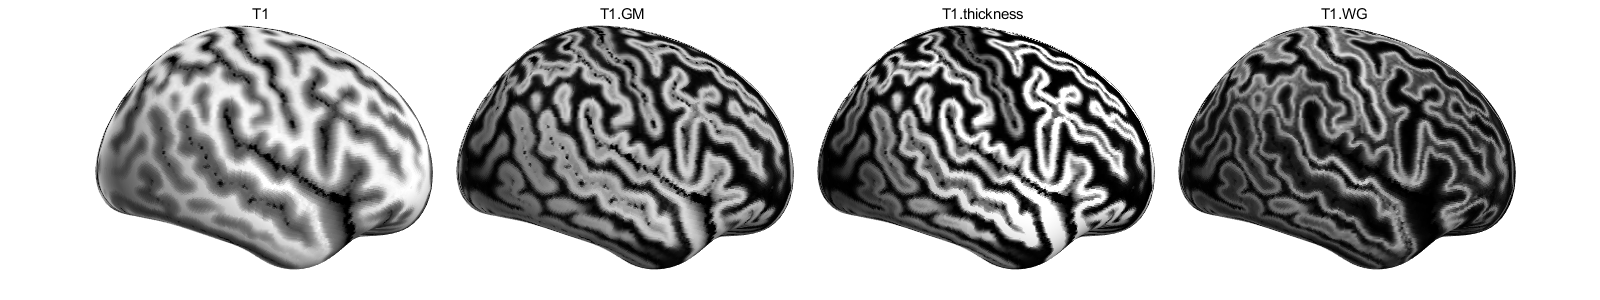

mni_XYZbin = zeros(Nxy/2,Nxy/2,Nz,3);
for i = 1:Nz
    temp = imresize_grid(mni_XYZ8c.data(:,:,i,:),[Nxy,Nxy]/2);
    mni_XYZbin(:,:,i,:) = permute(temp,[1,2,4,3]);
end

mni_depthbin = mni_depth3D.data(1:2:end,1:2:end,:);

mni_XYZbin = mni_XYZ8c;
mni_depthbin = 0*mni_XYZbin.data(:,:,:,1);

pilo_z = 30; view_dir = [90,0]; zoom_lv = 1.25;
plot_pilos_cell(map_tex3D,mni_XYZbin,fea_names,pilo_z,view_dir,zoom_lv)

% lay_fig('func','clim([0,255])'); colormap turbo

# std map cluster

# 1-SSIM mean map

i_list = 1:length(sub_dirs);

reg_type = 'infreg';
switch reg_type
    case 'mni'
        reg_tag = 'T1_rb/T1.mni2_reg.nii.gz';
    case 'infreg'
        reg_tag = 'save\feaMAP\FEA_T1.nii.gz';
end

ii = 0;
for i = 1:length(i_list)
    disp_wait(i,length(i_list))

    sub_dir = sub_dirs(i_list(i)).name;
    subj_dir = [root_dir,sub_dir,'/'];
 
    reg_file = [subj_dir,reg_tag];
    if isfile(reg_file)
        ii = ii+1;
        mri_raw = MRI_read_Data([subj_dir,'/T1_rb/T1.reg.norm.nii.gz'],'verbose',0);
        mri_raw = mat_cut(3*mri_raw.data-1);

        switch reg_type
            case 'elas'
                mri_reg = mat_cut(3*mni_norm.data-1);
            case 'mni'
                mri_reg = MRI_read_Data(reg_file,'verbose',0);
                mri_reg = mat_cut(3*mri_reg.data-1);
            case 'infreg'
                mri_reg = MRI_read_Data(reg_file,'verbose',0);
                mri_reg = mri_reg.data;
        end

        mri_reg = mri_reg.*mat_cut(mri_raw*2,0,1);

        [score,qualityMaps] = multissim3(mri_raw,mri_reg);

        if ii == 1
            meanQuality = qualityMaps;
        else
            for j = 1:length(meanQuality)
                meanQuality{j} = meanQuality{j}+qualityMaps{j};
            end
        end
    end
end

  E 00:01:25 100% [=======================================>] R 00:00:06 Progress: 170/170 



for j = 1:length(meanQuality)
    meanQuality{j} = meanQuality{j}/ii;
end

meanQuals.(reg_types{i}) = meanQuality;

cortex_mask = MRI_read_Data(['D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig4\compare_reg\cortex_mask.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


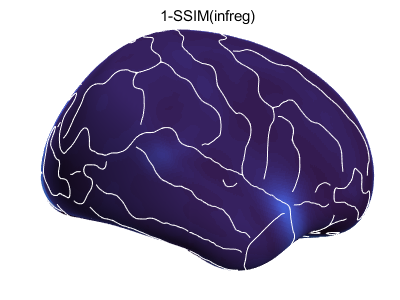

cortex_mask = single(cortex_mask.data);
qual_vol = (1-imresize3(meanQuality{2},size(mri_raw))).*cortex_mask;

[qual_tex3D,qual_Ren3D] = Pilo_gen(qual_vol,'XYZ',mni_XYZ8c,'Nxy',k*divN/2,'Nz',[],'tex_lim',{'1','99',1.5}, ...
        'alpha_list',[1,0.25],'proj_func',[],'proj_view','out','interp_method',1);

% qual_Ren3D.data = qual_Ren3D.data.*(edge_tex3D.data < 0.1);

plot_pilos_cell({qual_Ren3D},mni_XYZbin,{['1-SSIM(',reg_type,')']},30,[90,0],1)
lay_fig('func','clim([0,1])'); colormap turbo;
hold on; plot_surf(surf_edge_div,'EdgeColor',1+[0,0,0]); legend off

save_dir = 'D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig10\';
IO_mode = 'read';

reg_types = {'elas','mni','infreg'};
for i = 1:length(reg_types)
    switch IO_mode
        case 'save'
            meanQuality = meanQuals.(reg_types{i});
            qual_vol = (1-imresize3(meanQuality{2},size(mri_raw))).*cortex_mask;
            MRI_save_File(qual_vol,[save_dir,reg_types{i},'_meanQualVol2.nii.gz']);
        case 'read'
            meanQualVol = MRI_read_Data([save_dir,reg_types{i},'_meanQualVol2.nii.gz']);
            meanQualVols.(reg_types{i}) = meanQualVol;
    end
end

sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]


roi_id = [130,144,142, 226,224; 326,322,328 222,150];
roi_tags = sAtlas_meta.table.tag(sAtlas_meta.id_locs(roi_id));
roi_tags = fcellfun(@(x) x(1:end-2),roi_tags)

roi_tags = 2×5 cell 数组
    {'MFG'}    {'TrIFG'}    {'OplFG'}    {'AnG'}    {'SMG'}
    {'MTG'}    {'STG'  }    {'ITG'  }    {'PoG'}    {'PrG'}


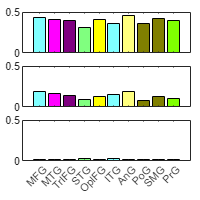


reg_types = {'elas','mni','infreg'};
for j = 1:length(reg_types)
    val_vol = meanQualVols.(reg_types{j}).data;
    for i = 1:length(roi_id(:))
        roi_vol = mri_atlas.data == roi_id(i);
        roi_volsum(j,i) = sum(val_vol.*roi_vol,'all')./sum(roi_vol,'all');
    end
end

% cOrder = lines(6); temp = [4,6,3];
figure; lay_sub(3,1)
for i = 1:3
    next; h = bar(roi_volsum(i,:));
    ylim([0,0.5]);
    h.FaceColor = 'flat';
    h.CData = atlas_cmap(1+roi_id(:),:);
    if i<3
        xticklabels({})
    else
        xticklabels(roi_tags(:))
    end
end
lay_fig([2,2])

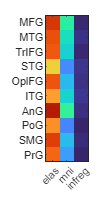


figure;
next; showd(roi_volsum'); clim([0,0.5])
axis ij; colormap turbo; yticklabels(roi_tags(:)); xticks(1:3); xticklabels(reg_types)
lay_fig([1,2]);

# atlas edge

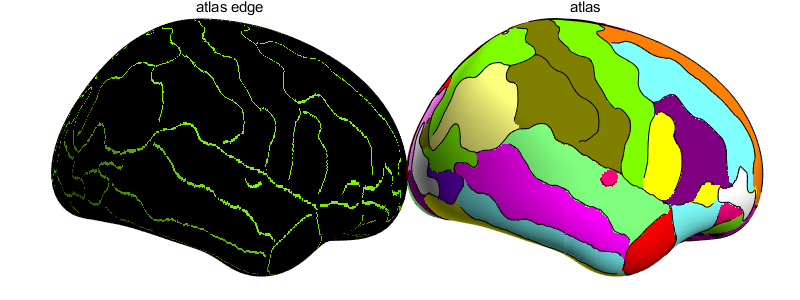

% mri_atlas = MRI_read_Data('D:\EXE\MRIcron\Resources\templates\aal.nii.gz');
% mri_atlas = MRI_func_ROI(mri_atlas,'repos',mni_norm);
mri_atlas = mni_atlas;
mni_XYZbin = mni_XYZ8c;

temp = mri_atlas.data;
temp = medfilt3(temp,5*[1,1,1]);
% temp = edge3(temp,'sobel',1e-8);

[atlas_tex3D,~] = Pilo_gen(temp,'XYZ',mni_XYZ8c,'Nxy',k*divN/2,'Nz',[],'tex_lim',{'1','99',1.5}, ...
        'alpha_list',[1,0.25],'proj_func',[],'proj_view','out','interp_method',0);
atlas_tex3D = atlas_tex3D.data;

atlas_tex3D = medfilt3(atlas_tex3D,[5,5,1]);
edge_tex3D = 0*atlas_tex3D;
for i = 1:size(edge_tex3D,3)
    % edge_tex3D.data(:,:,i) = single(bwskel(edge_tex3D.data(:,:,i)>0));
    edge_tex3D(:,:,i) = edge(atlas_tex3D(:,:,i),'canny',1e-7);
end
edge_tex3D = single(edge_tex3D);

h_surf8c = plot_pilos_cell({edge_tex3D,atlas_tex3D},mni_XYZbin,{'atlas edge','atlas'},29,[90,0],0.8);
colormap(atlas_cmap); clim([0,size(atlas_cmap,1)])

surf_edge = Surf_read_Data(surf2patch(h_surf8c{1}));
surf_edge = Surf_func_ROI(surf_edge,'resize8c',5);

surf_edge_div = Surf_func_ROI(surf_edge,'divide',surf_edge.facevertexcdata==0);
surf_edge_div = surf_edge_div{1};
surf_edge_div = Surf_smooth(surf_edge_div,10);

hold on; plot_surf(surf_edge_div,'EdgeColor',0*[1,1,1]); view([90,0]); legend off

# out cluster of extension and junction map

map_type = 'junction';

ii = 0;
out_map_mean = 0;
roi_mean = 0;
for i = 1:length(i_list)
    disp_wait(i,length(i_list))

    sub_dir = sub_dirs(i_list(i)).name;
    subj_dir = [root_dir,sub_dir,'\'];

    switch map_type
        case 'extension'
            mri_tag = ['\save\MAP18\extension_map_',sub_dir];
        case 'junction'
            mri_tag = ['\save\MAP18\junction_map_',sub_dir];
        case 'resGM'
            mri_tag = ['\save\resMAP\resFEA_T1.GM'];
        case 'resWG'
            mri_tag = ['\save\resMAP\resFEA_T1.WG'];
    end

    map_file = [subj_dir,mri_tag,'.nii.gz'];
    if isfile(map_file)
        ii = ii+1;
        mri_map = MRI_read_Data(map_file,'verbose',0);
        mri_roi = MRI_read_Data([subj_dir,'/T1_rb/FLAIR_roi_reg.nii.gz'],'verbose',0);

        mri_map = amp(mri_map.data,1e-3);
        mri_map_out = mri_map.*(mri_roi.data<1);

        out_map_mean = out_map_mean + mri_map_out;
        roi_mean = roi_mean + single(mri_roi.data);
    end
end


  E 00:00:59 100% [=======================================>] R 00:00:05 Progress: 170/170 


out_map_mean = out_map_mean/ii;
out_map_mean = imgaussfilt3(out_map_mean+fliplr(out_map_mean),3)/2;
roi_mean = roi_mean/ii;
roi_mean = imgaussfilt3(roi_mean+fliplr(roi_mean),3)/2;

eval([map_type,'_map_mean = out_map_mean;'])

segPrctile_func = @(x,a) x>prctile(x(:),a);


vol_A = roi_mean.data.*cortex_mask;
vol_B = out_map_means.resWG.data.*cortex_mask;
vol_add = segPrctile_func(vol_A,95) + 2*segPrctile_func(vol_B,96);
vol_IoU = sum(vol_add==3, 'all')./sum(vol_add>=1, 'all')

[vol_tex3D,vol_Ren3D] = Pilo_gen(vol_add,'XYZ',mni_XYZ8c,'Nxy',k*divN/2,'Nz',[],'tex_lim',{'1','99',1.5}, ...

vol_IoU =       0.24789


        'alpha_list',[1,0.25],'proj_func',[],'proj_view','out','interp_method',0);

plot_pilos_cell({vol_tex3D.data},mni_XYZbin,{"IoU = "+round(vol_IoU,3)},30,[90,0],1)
colormap turbo; clim([0,3]); colormap([0,0,0; 1,0,0; 0,1,0; 1,1,0])
hold on; plot_surf(surf_edge_div,'EdgeColor',1+[0,0,0]); legend off

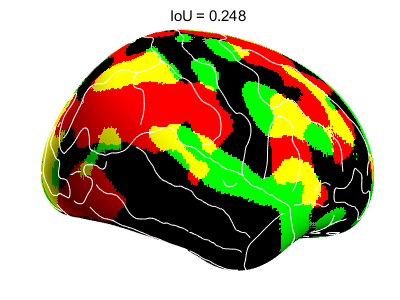

save_dir = 'D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig10\';
IO_mode = 'read';


map_types = {'extension','junction','resGM','resWG'};
for i = 1:length(map_types)
    switch IO_mode
        case 'save'
            out_map_mean = out_map_means.(map_types{i});
            MRI_save_File(out_map_mean,[save_dir,map_types{i},'_meanOutMap.nii.gz']);
        case 'read'
            out_map_mean = MRI_read_Data([save_dir,map_types{i},'_meanOutMap.nii.gz']);
            out_map_means.(map_types{i}) = out_map_mean;
    end
end
switch IO_mode
    case 'save'
        MRI_save_File(roi_mean,[save_dir,map_types{i},'FCDroi_meanMap.nii.gz']);

sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]


    case 'read'
        roi_mean = MRI_read_Data([save_dir,map_types{i},'FCDroi_meanMap.nii.gz']);
end

sMRI [229,193,193] res:[1,1,1]


roi_id = [130,144,142, 226,224; 326,322,328 222,150];
roi_tags = sAtlas_meta.table.tag(sAtlas_meta.id_locs(roi_id));
roi_tags = fcellfun(@(x) x(1:end-2),roi_tags)

roi_tags = 2×5 cell 数组
    {'MFG'}    {'TrIFG'}    {'OplFG'}    {'AnG'}    {'SMG'}
    {'MTG'}    {'STG'  }    {'ITG'  }    {'PoG'}    {'PrG'}


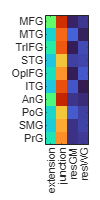


map_types = {'extension','junction','resGM','resWG'};
for j = 1:length(map_types)
    val_vol = out_map_means.(map_types{j}).data;
    for i = 1:length(roi_id(:))
        roi_vol = mri_atlas.data == roi_id(i);
        roi_volsum(j,i) = sum(val_vol.*roi_vol,'all')./sum(roi_vol,'all');
    end
end

figure;
next; showd(roi_volsum'); clim([0,0.15])
axis ij; colormap turbo; yticklabels(roi_tags(:)); xticks(1:length(map_types)); xticklabels(map_types)
lay_fig([1,2]);

# sulci atlas evaluation for mean maps

sulc_atlas_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\sulci_atlas\';
sulc_atlas_max = MRI_read_Data([sulc_atlas_dir,'mni_sulc_max.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


sulc_atlas_cb = MRI_read_Data([sulc_atlas_dir,'mni_sulc_cb.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


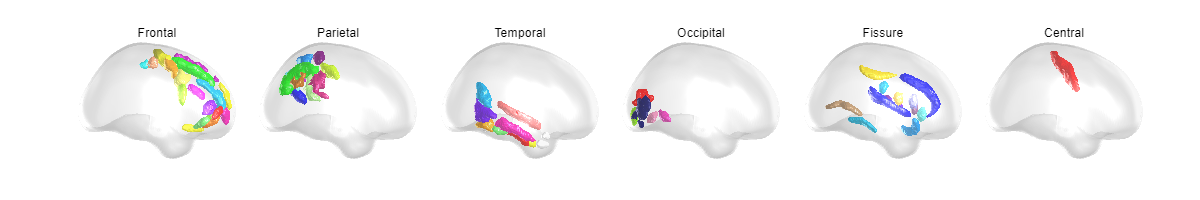

load([sulc_atlas_dir,'sulc_groups.mat']);

func_plotbnd = @()plot_surf(mni_bnd8c,[1,1,1]*0.9,'alphas',0.3);

figure; lay_sub(1,max(sulc_lobeID))
for i = 1:max(sulc_lobeID)
    next; plot_surf(sulc_surfs(sulc_lobeID == i & ismember(sulc_LR,'right'))); %lgd = plot_legend; lgd.Location = 'bestoutside';
    hold on; func_plotbnd(); legend off; axis off; title(sulc_lobeName{i})
end
lay_fig([12,2]); lay_linkview; view(90,0)

eval_methods = 'edge_mean';

mris_filt = mris;
switch eval_methods
    case 'mean'
    case 'edge_mean'
        for j = 1:length(mris)
            for i = 1:size(mris{j},3)
                mris_filt{j}(:,:,i) = fibermetric(mris{j}(:,:,i),[2,3]);
            end
            mris_filt{j} = mris_filt{j}>0.9*max(mris_filt{j}(:));
        end
end

for i = 1:6
    roi_id = find(ismember(sulc_lobeID,i));
    temp = sulc_atlas_cb.data;
    roi_vol = ismember(floor(temp),roi_id);
    roi_vol = single(roi_vol)*2.*(temp-floor(temp));

    roi_vol = imgaussfilt3(single(roi_vol>0.5),1)>0.2;

    for j = 1:length(mris)
        switch eval_methods
            case 'mean'
                vals(j,i) = sum(mris_filt{j}.*roi_vol,'all')/sum(roi_vol,'all');
            case 'edge_mean'
                vals(j,i) = sum(mris_filt{j}.*roi_vol,'all')/sum(roi_vol,'all');
        end
    end
end

vals

vals = 4×6 single 矩阵
       0.1085      0.13915      0.11347      0.14941      0.12702      0.18687
      0.22027      0.23836      0.13963      0.12166      0.18301      0.29112
      0.34188      0.32793      0.35772      0.29243      0.32976      0.35925
      0.12297      0.14556       0.1101       0.1319     0.067532      0.22031



% for j = 1:fea_num
% [roi_tex3D{j},roi_Ren3D{j}] = Pilo_gen(mris{j}.*roi_vol,'XYZ',mni_XYZ8c,'Nxy',k*divN/2,'Nz',[],'tex_lim',{'1','99',1.5}, ...
%         'alpha_list',[1,0.25],'proj_func',[],'proj_view','out');
% end
% plot_pilos_cell(roi_Ren3D,mni_XYZbin,fea_names); colormap([0,0,0;turbo])

# read evalution table and plot

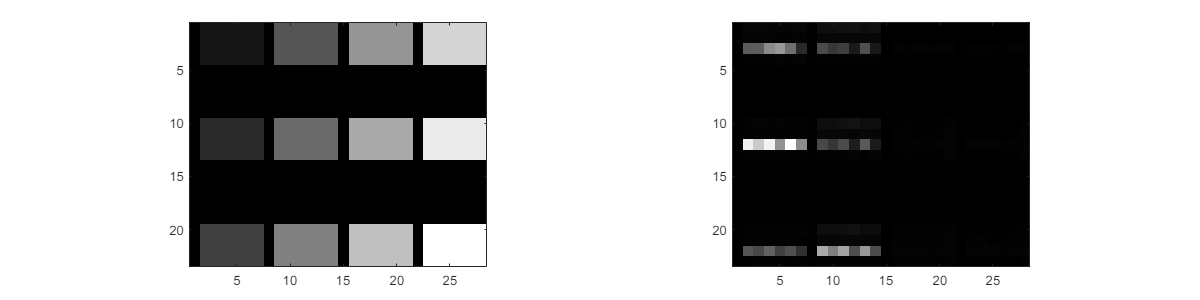

tab_file = 'D:\Doc\投稿论文\FCD\flatReg\Fig_material\tables\meanMap_sulc_eval.xlsx';

tab_data = readtable(tab_file);
tab_data = table2cell(tab_data);
tab_data = cellfun(@data2double,tab_data);
tab_isnum = ~isnan(tab_data);
tab_bwlabel = bwlabel(tab_isnum);
tab_bwstats = regionprops(tab_isnum);

figure;
next; showc(tab_bwlabel); next; showc(tab_data)
lay_fig([12,3]); colormap gray

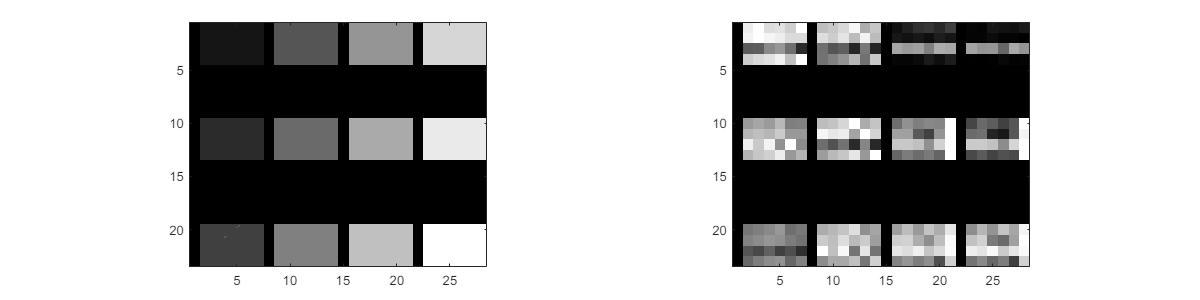

tab_labelnum = max(tab_bwlabel(:));

tab_N = 3;
tab_M = 4;
tab_datacell = cell(tab_N,tab_M);
for i = 1:tab_labelnum
    temp = tab_data(tab_bwlabel == i);
    tab_datacell{i} = reshape(temp,tab_bwstats(i).BoundingBox([4,3]));
end

data_max = [];
for i = 1:tab_M
    for j = 1:tab_N
        data_max{i}(:,j) = max(tab_datacell{j,i},[],2);
    end
    data_max{i} = max(data_max{i},[],2);
end

tab_normcell = tab_datacell;
tab_datanorm = tab_data;
ii = 0;
for i = 1:tab_M
    for j = 1:tab_N
        ii = ii+1;
        tab_normcell{j,i} = tab_datacell{j,i}./data_max{i};
        tab_datanorm(tab_bwlabel == ii) = tab_normcell{j,i}(:);
    end
end

figure;
next; showc(tab_bwlabel); next; showc(tab_datanorm)
lay_fig([12,3]); colormap gray

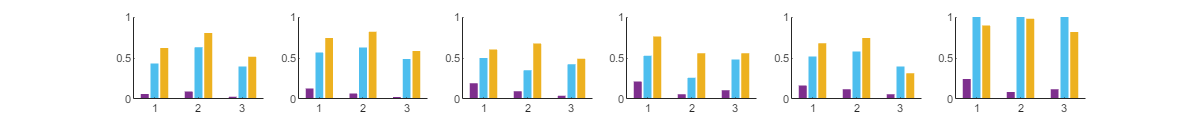

figure
for i = 1:size(tab_normcell{1},2)
    data_sel = fcellfun(@(x) x(:,i)', tab_normcell(:,3));
    data_sel = cell2mat(data_sel);

    data_sel = data_sel(:,[1,2,4]);

    next; bar(data_sel','EdgeColor','none'); ylim([0,1])
    if i>10
        axis off
    else
        box off
    end
end
lay_fig([12,1.25])

temp = lines(6);
colororder(temp([4,6,3],:))

# MAP18 reference mean map using shooting registration

map18ref_dir = 'F:\Dataset\Brain\FCD_maps\data\control\ZYS\reference\';

function x = remove_nan(x)
if isstruct(x)
    x.data(isnan(x.data)) = 0;
else
    x(isnan(x)) = 0;
end
end

function w = weighting_sing(x,a)
w_factor = 3; % 越大，加权中心越尖
f = @(x) exp(-w_factor*abs(x-a));
w = (f(x)-f(a+1))/(1-f(a+1));
w(w<0) = 0;
end

function w = weighting_mult(x,a)
w = weighting_sing(x,a);
wsum = weighting_sing(x,0) + weighting_sing(x,1)+ weighting_sing(x,2);
w = w./wsum;
end

function [data,warp_type] = get_multiFeatures(LAB,subj_dir,feature_id)
warp_type = 1;
switch feature_id
    case 1
        data = LAB;
    case 2
        GM = 1 - 1*abs(LAB - 1);
        GM(GM<0) = 0;

        data = GM.^1;
    case 3
        Grad = LAB;
        Grad(Grad<1) = 1;
        Grad = imgradient3(Grad);

        Gradcut = mat_cut(1 - 2*abs(Grad/10 - 1));
        %Gradcut = imgaussfilt3(Gradcut,1);
        data = Gradcut;
    case 4
        WG = LAB;
        WG = 1 - 2*abs(WG-1.5);
        WG(WG<0) = 0;
        % SE = strel("sphere",1);
        % WG = imerode(WG,SE);

        data = WG.^1;
    case 5
        T1_thickness = MRI_read_Data([subj_dir,'\T1_rb\T1.GMsep.thickness_reg.nii.gz'],'verbose',0);
        data = T1_thickness.data;
    case 6
        FLAIR = MRI_read_Data([subj_dir,'\T1_rb\mFLAIR_reg.nii.gz'],'verbose',0);
        % data = FLAIR.data./mean(FLAIR.data(:));
        data = FLAIR.data./20000;
    case 7
        T1_depth = MRI_read_Data([subj_dir,'\T1_rb\T1.GMsep.depth_reg.nii.gz'],'verbose',0);
        data = T1_depth.data;
    case 8
        WGmap = MRI_read_Data([subj_dir,'\T1_rb\T1.WGmap_reg.nii.gz'],'verbose',0);
        data = WGmap.data;
    case 9
        curv = MRI_read_Data([subj_dir,'\T1_rb\T1.GM.curvtureABS_reg.nii.gz'],'verbose',0);
        data = mat_cut(curv.data);
    otherwise
        warp_type = 0;
end

data = remove_nan(single(data));
end

function [D,moving_warp] = imreg_demons(Im0,If0,reg_iter,box)
Im = Im0(box(1):box(4),box(2):box(5),box(3):box(6));
If = If0(box(1):box(4),box(2):box(5),box(3):box(6));

[D,moving_reg] = imregdemons(gpuArray(Im),gpuArray(If),reg_iter,'PyramidLevels',1);

moving_warp = 0*If0;
moving_warp(box(1):box(4),box(2):box(5),box(3):box(6)) = gather(moving_reg);
end

function varargout = plot_pilos_cell(map_Ren3D,mni_XYZbin,titles,pilo_z,view_dir,zoom_lv)
% mni_depthbin = 0*mni_XYZbin.data(:,:,:,1);

map_num = length(map_Ren3D);
ax = [];
figure; lay_sub(1,map_num)
for j = 1:map_num
    ax{j} = next;

    temp = map_Ren3D{j};
    % temp = amp(temp,0.04);

    [~,h_surf8c{j}] = plot_pilos(mni_XYZbin,temp,[],'depth3D',[],'parent',ax{j});
    ax{j}.UserData.depth_change_fcn(pilo_z)
    view(view_dir); axis off; legend off; title(titles{j});
    pause(1)
end
lay_fig([4*map_num,3]);
sld = findobj('Tag','z_slider'); delete(sld)
if map_num>1
    for j = 1:map_num
        axes(ax{j}); camzoom(zoom_lv);
        ax{j}.CameraViewAngle = ax{1}.CameraViewAngle;
    end
    lay_linkview
end

if nargout>0
    varargout = {h_surf8c};
end
end

function x = data2double(x)
if ~isnumeric(x)
    x = NaN;
end
end